# **Simple 1D Minimization**

We're going to create a simple optimizer for 1D functions and use the following unimodal convex function as a test for out optimizer  

f(x) = 3(x-3)^4 +4ln(x)

`Our function is defined in matlab as follows`

f = @(x) 3*(x-3).^4 + 4*log(x)

f = function_handle with value:
    @(x)3*(x-3).^4+4*log(x)


`With the plot as seen below`

u = linspace(1, 5, 100);
y = f(u);

y =    48.0000   44.3956   41.0109   37.8370   34.8655   32.0877   29.4954   27.0804   24.8347   22.7506   20.8204   19.0365   17.3917   15.8790   14.4912   13.2217   12.0638   11.0113   10.0578    9.1973    8.4240    7.7322    7.1164    6.5714    6.0920    5.6734    5.3107    4.9994    4.7353    4.5141    4.3318    4.1847    4.0692    3.9818    3.9193    3.8788    3.8573    3.8523    3.8612    3.8818    3.9120    3.9499    3.9938    4.0423    4.0939    4.1476    4.2025    4.2578    4.3129    4.3674


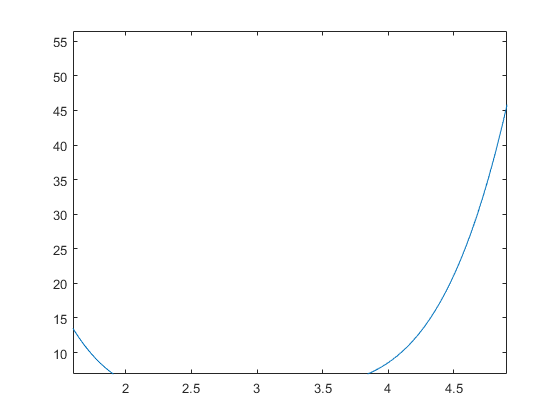

plot(u, y);

`From here, you'll need to start adding your own code.`

`Let's take our first a second derivatives as these will be useful later.`

fp = @(x)  %YOUR FIRST DERIVATIVE HERE
fpp = @(x) % YOUR SECOND DERIVATIVE HERE

`Next, let's recal that the derivative for unimodal convex functions is the location where the first derivative is 0.  In order to do this, we're going to create a first order newton solver for the zeros of our first derivative.  `

`This function should take in a function, it's derivative, and a starting point for the iteration  `

`Recall the function for newton iteration is as follows  `

`$``x_{k+``1``} = x_k - f(x_k)/f'(x_k)``$`

`You should iterate until your relative tolerance between $``x_{k+``1``}``$ and $``x_k``$ is less than 0.00001`

`Define your code for this function in the newton_minimize.m file`

minima = newton_minimize(fp, fpp, 5)  % This code calls your function
print('The minima is ', minima)